% ====================================================
% Lab 1.2 Magnetic Sensor - Data Processing Script
% ====================================================

clear; clc; close all;

% --- Parameters ---
V_Q   = 1650;
Sens  = 7.5;
V_ref = 3300;

% --- Folder structure ---
base_dir = 'Data';
conditions = {
    'South(Plus)_set1',    'South(Plus)_set2',    'South(Plus)_set3';
    'South(Plus)_S_set1',  'South(Plus)_S_set2',  'South(Plus)_S_set3';
    'North(minus)_set1',   'North(minus)_set2',   'North(minus)_set3';
    'North(minus)_S_set1', 'North(minus)_S_set2', 'North(minus)_S_set3'
};
condition_names = {
    'South No Shield';
    'South Shield';
    'North No Shield';
    'North Shield'
};
set_colors = {'#0072BD', '#D95319', '#77AC30'};

% ====================================================
% STEP 1: Load, recalculate B, overwrite CSV
% ====================================================
all_data = cell(4,3);
for c = 1:4
    for s = 1:3
        folder   = fullfile(base_dir, conditions{c,s});
        csv_file = fullfile(folder, 'Lab1_2_Magnetic_Results.csv');
        T        = readtable(csv_file);
        T.B_mT   = (T.V_out_mV - V_Q) / Sens;
        writetable(T, csv_file);
        all_data{c,s} = T;
        fprintf('Recalculated: %s\n', conditions{c,s});
    end
end

Recalculated: South(Plus)_set1
Recalculated: South(Plus)_set2
Recalculated: South(Plus)_set3
Recalculated: South(Plus)_S_set1
Recalculated: South(Plus)_S_set2
Recalculated: South(Plus)_S_set3
Recalculated: North(minus)_set1
Recalculated: North(minus)_set2
Recalculated: North(minus)_set3
Recalculated: North(minus)_S_set1
Recalculated: North(minus)_S_set2
Recalculated: North(minus)_S_set3


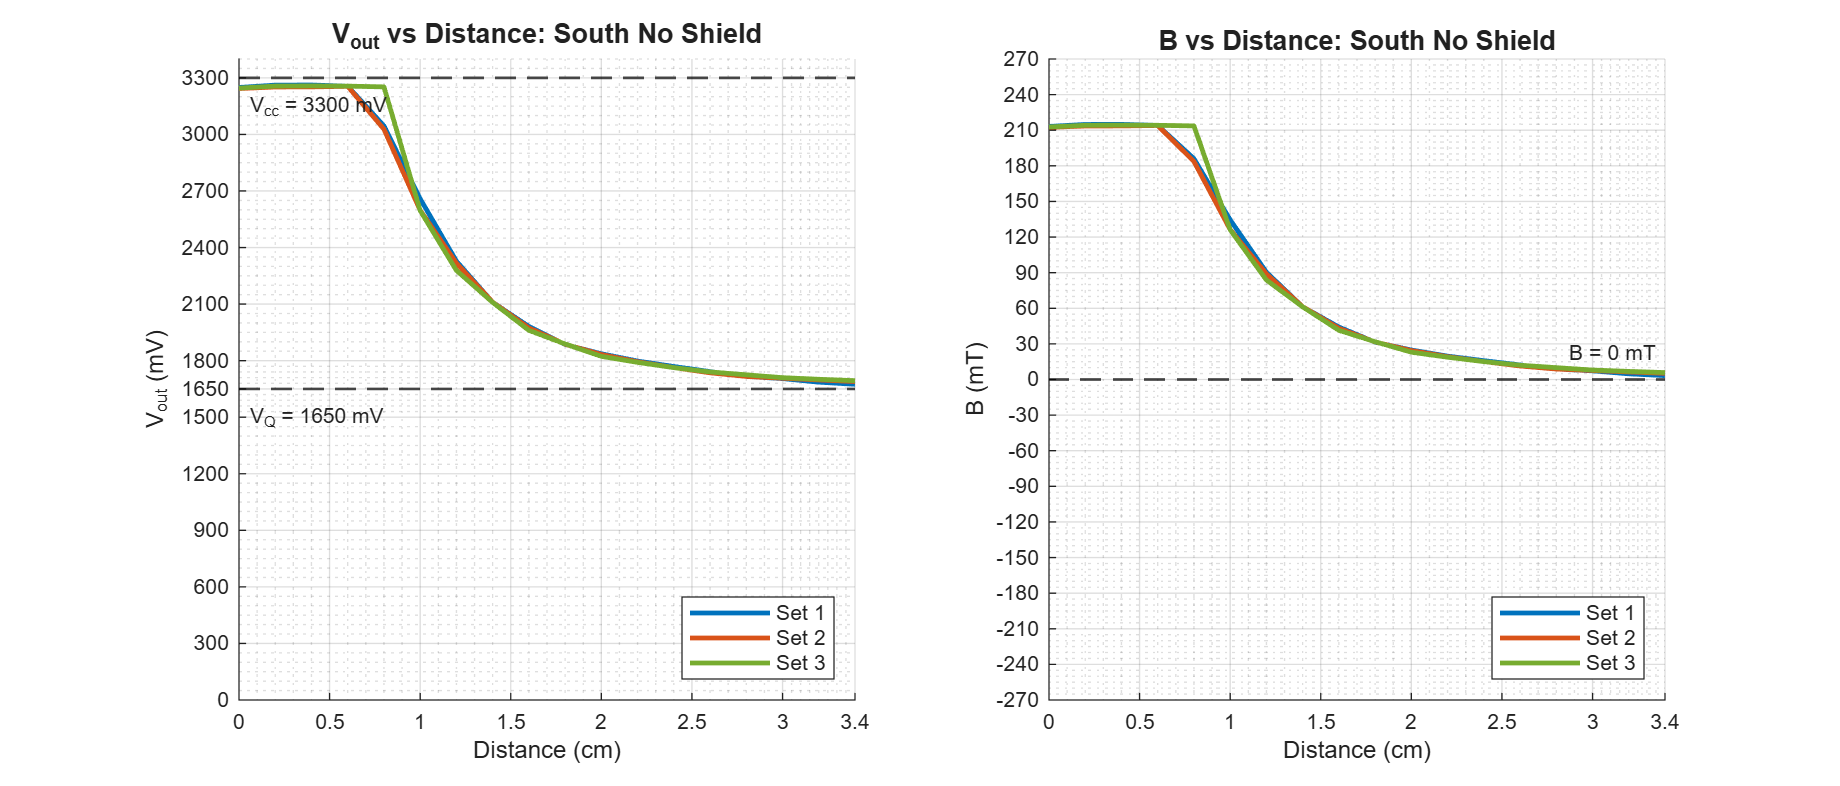

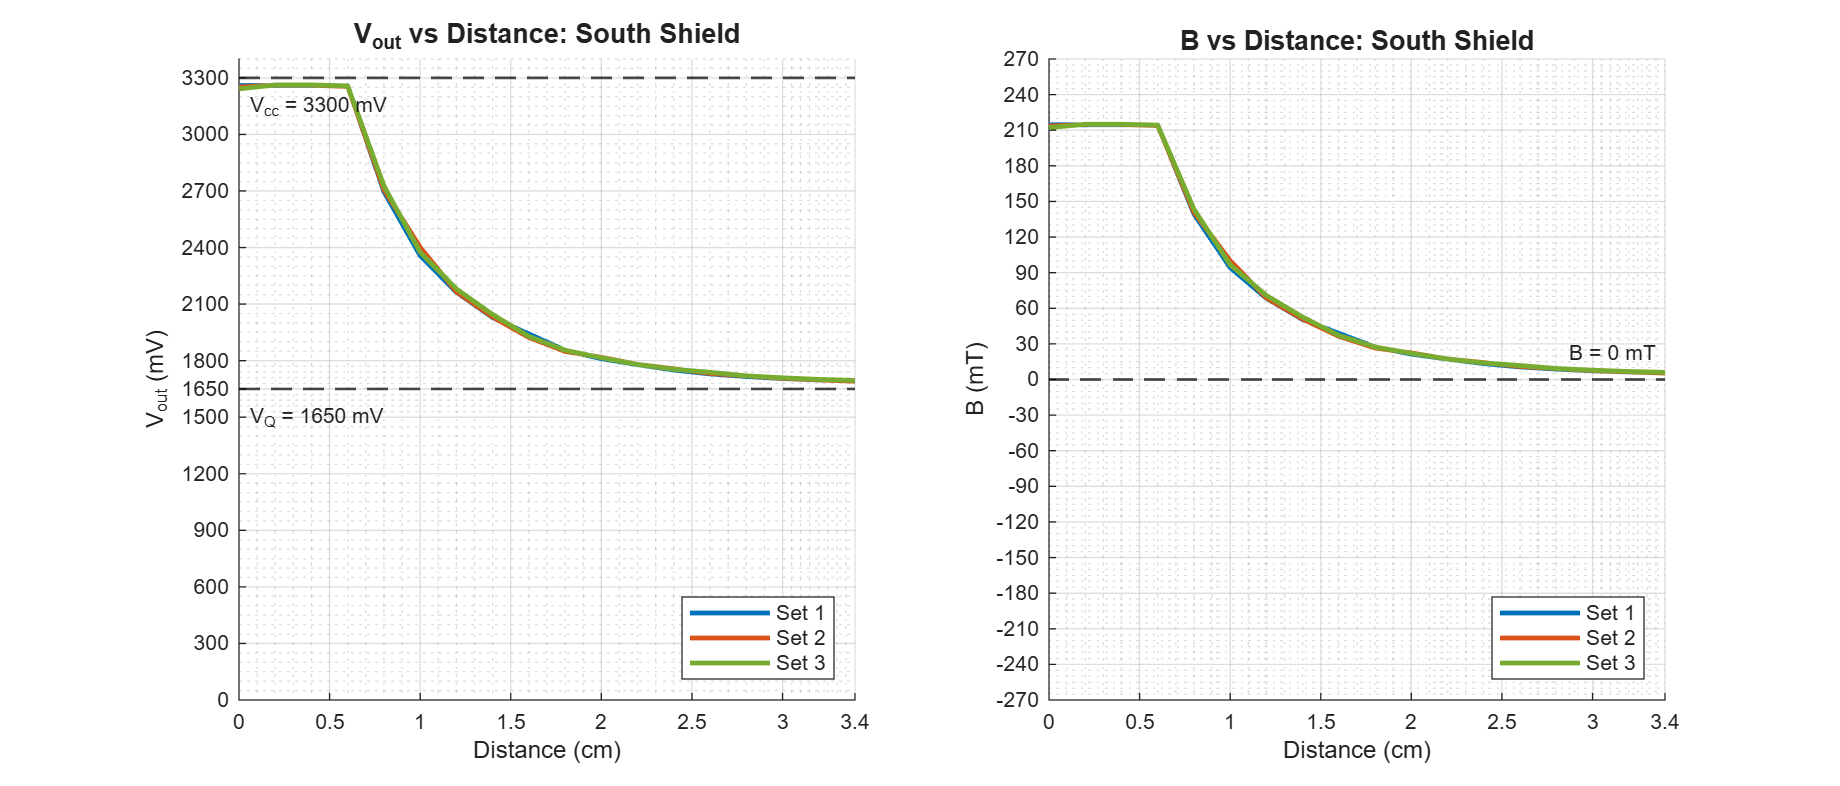

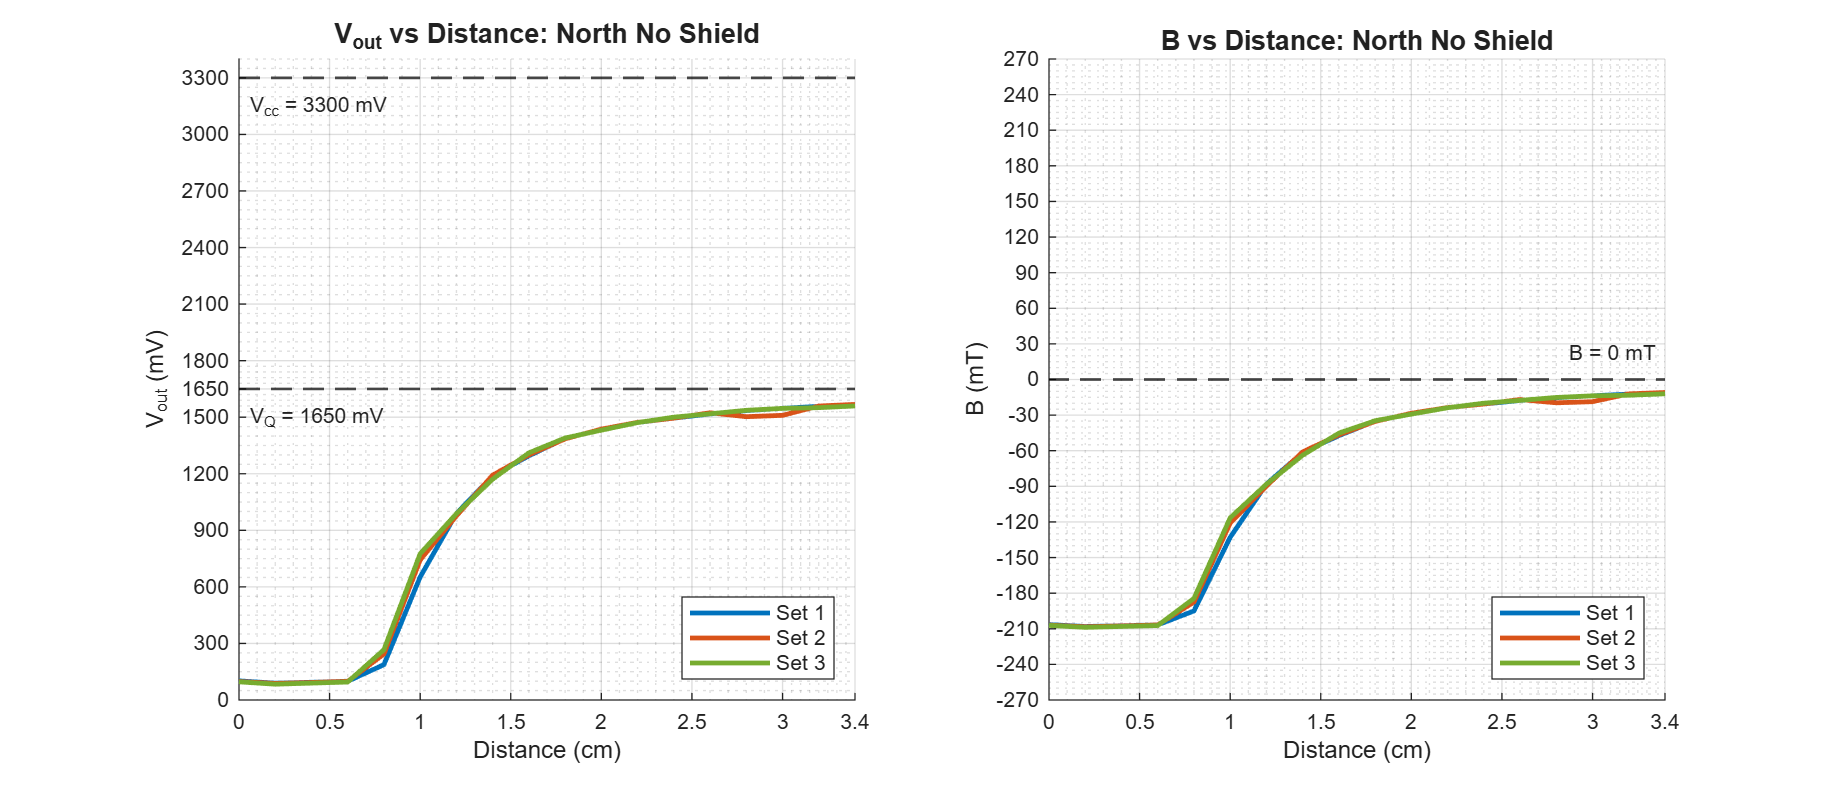

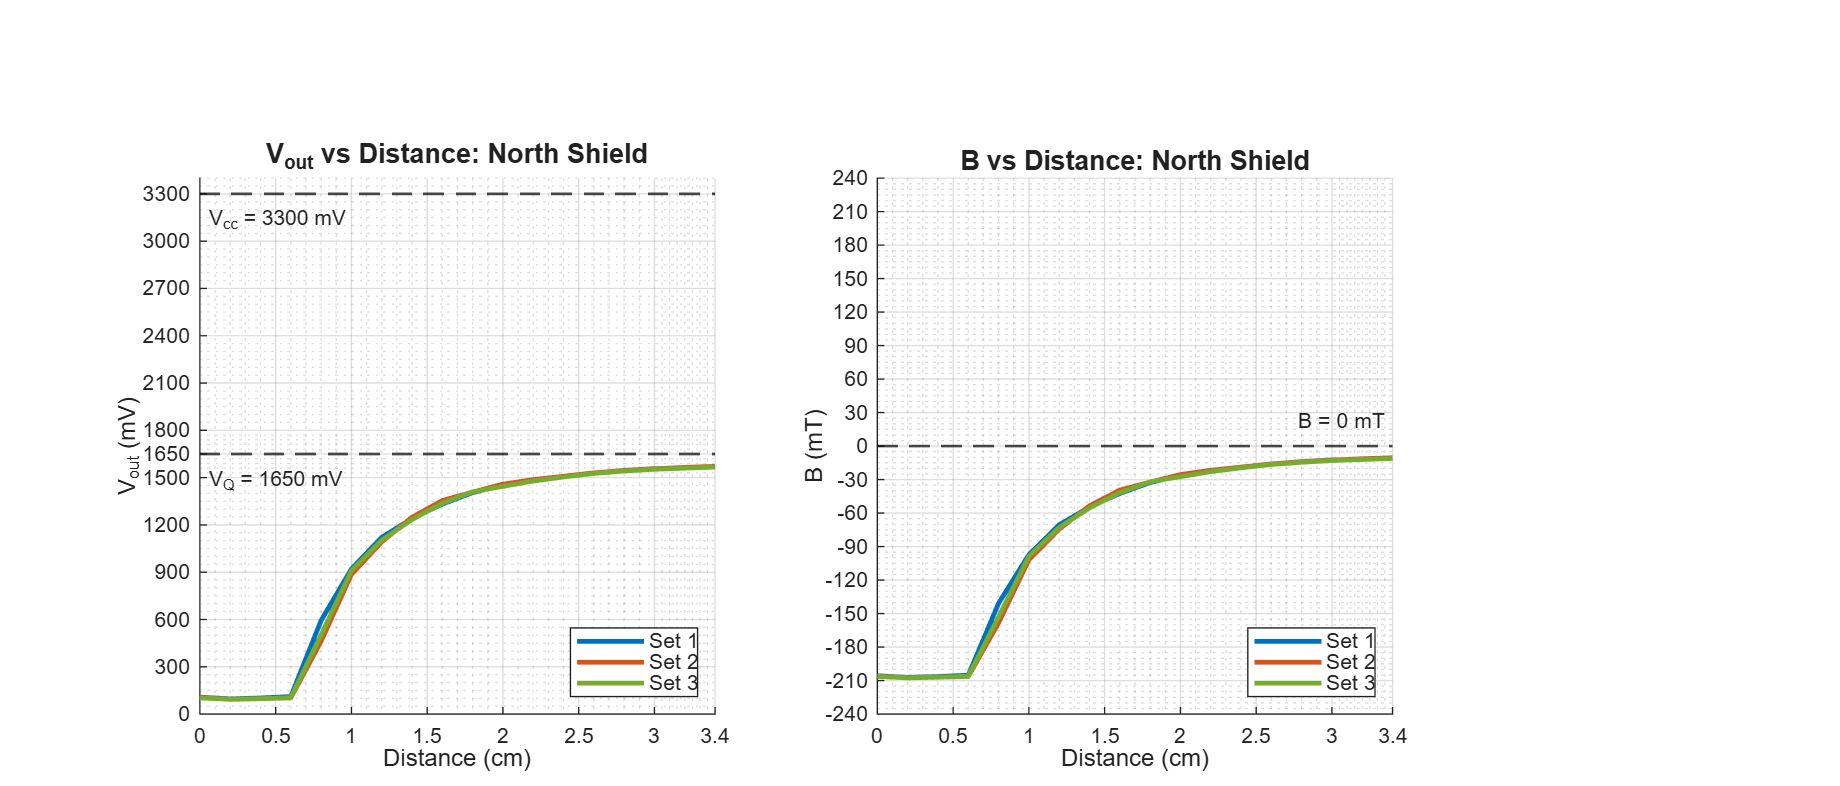


% ====================================================
% STEP 2: Vout vs d  +  B vs d
% ====================================================
x_lo    = 0;
x_hi    = 3.4;
x_ticks = [0, 0.5, 1.0, 1.5, 2.0, 2.5, 3.0, 3.4];  % explicit include 3.4
font_ax = 8;   % axis tick label size

for c = 1:4
    fig = figure('Position',[100 100 1100 470]);

    all_vout = cell2mat(arrayfun(@(s) all_data{c,s}.V_out_mV, (1:3)', 'UniformOutput',false));
    all_b    = cell2mat(arrayfun(@(s) all_data{c,s}.B_mT,    (1:3)', 'UniformOutput',false));
    all_vout = all_vout(:);
    all_b    = all_b(:);

    % ---- LEFT: Vout vs d ----
    ax1 = subplot(1,2,1); hold on;

    for s = 1:3
        T = all_data{c,s};
        plot(T.Distance_cm, T.V_out_mV, ...
            'Color', set_colors{s}, 'LineWidth', 1.8, ...
            'DisplayName', sprintf('Set %d', s));
    end

    yline(V_Q,   '--k', 'LineWidth', 1.0, 'HandleVisibility','off');
    yline(V_ref, '--k', 'LineWidth', 1.0, 'HandleVisibility','off');

    text(0.05, V_ref - 80, 'V_{cc} = 3300 mV', ...
        'FontSize', font_ax, 'HorizontalAlignment','left', 'VerticalAlignment','top');
    text(0.05, V_Q - 80, 'V_Q = 1650 mV', ...
        'FontSize', font_ax, 'HorizontalAlignment','left', 'VerticalAlignment','top');

    ylim([0, 3400]);
    yticks(unique([0, 300:300:1500, 1650, 1800:300:3300]));
    ax1.YAxis.FontSize = font_ax;

    xlim([x_lo, x_hi]);
    xticks(x_ticks);
    ax1.XAxis.FontSize = font_ax;

    xlabel('Distance (cm)', 'FontSize', font_ax+1);
    ylabel('V_{out} (mV)',  'FontSize', font_ax+1);
    title(sprintf('V_{out} vs Distance: %s', condition_names{c}), 'FontSize', 10);
    legend('Location','southeast', 'FontSize', font_ax);
    grid on; grid minor;

    % ---- RIGHT: B vs d ----
    ax2 = subplot(1,2,2); hold on;

    for s = 1:3
        T = all_data{c,s};
        plot(T.Distance_cm, T.B_mT, ...
            'Color', set_colors{s}, 'LineWidth', 1.8, ...
            'DisplayName', sprintf('Set %d', s));
    end

    yline(0, '--k', 'LineWidth', 1.0, 'HandleVisibility','off');

    dev2  = max(abs(all_b)) * 1.15;
    step2 = 30;
    yl2   = ceil(dev2 / step2) * step2;

    text(3.35, step2*0.4, 'B = 0 mT', ...
        'FontSize', font_ax, 'HorizontalAlignment','right', 'VerticalAlignment','bottom');

    ylim([-yl2, yl2]);
    yticks(-yl2:step2:yl2);
    ax2.YAxis.FontSize = font_ax;

    xlim([x_lo, x_hi]);
    xticks(x_ticks);
    ax2.XAxis.FontSize = font_ax;

    xlabel('Distance (cm)', 'FontSize', font_ax+1);
    ylabel('B (mT)',        'FontSize', font_ax+1);
    title(sprintf('B vs Distance: %s', condition_names{c}), 'FontSize', 10);
    legend('Location','southeast', 'FontSize', font_ax);
    grid on; grid minor;

    saveas(fig, sprintf('fig_%02d_%s.png', c, strrep(condition_names{c},' ','_')));
end

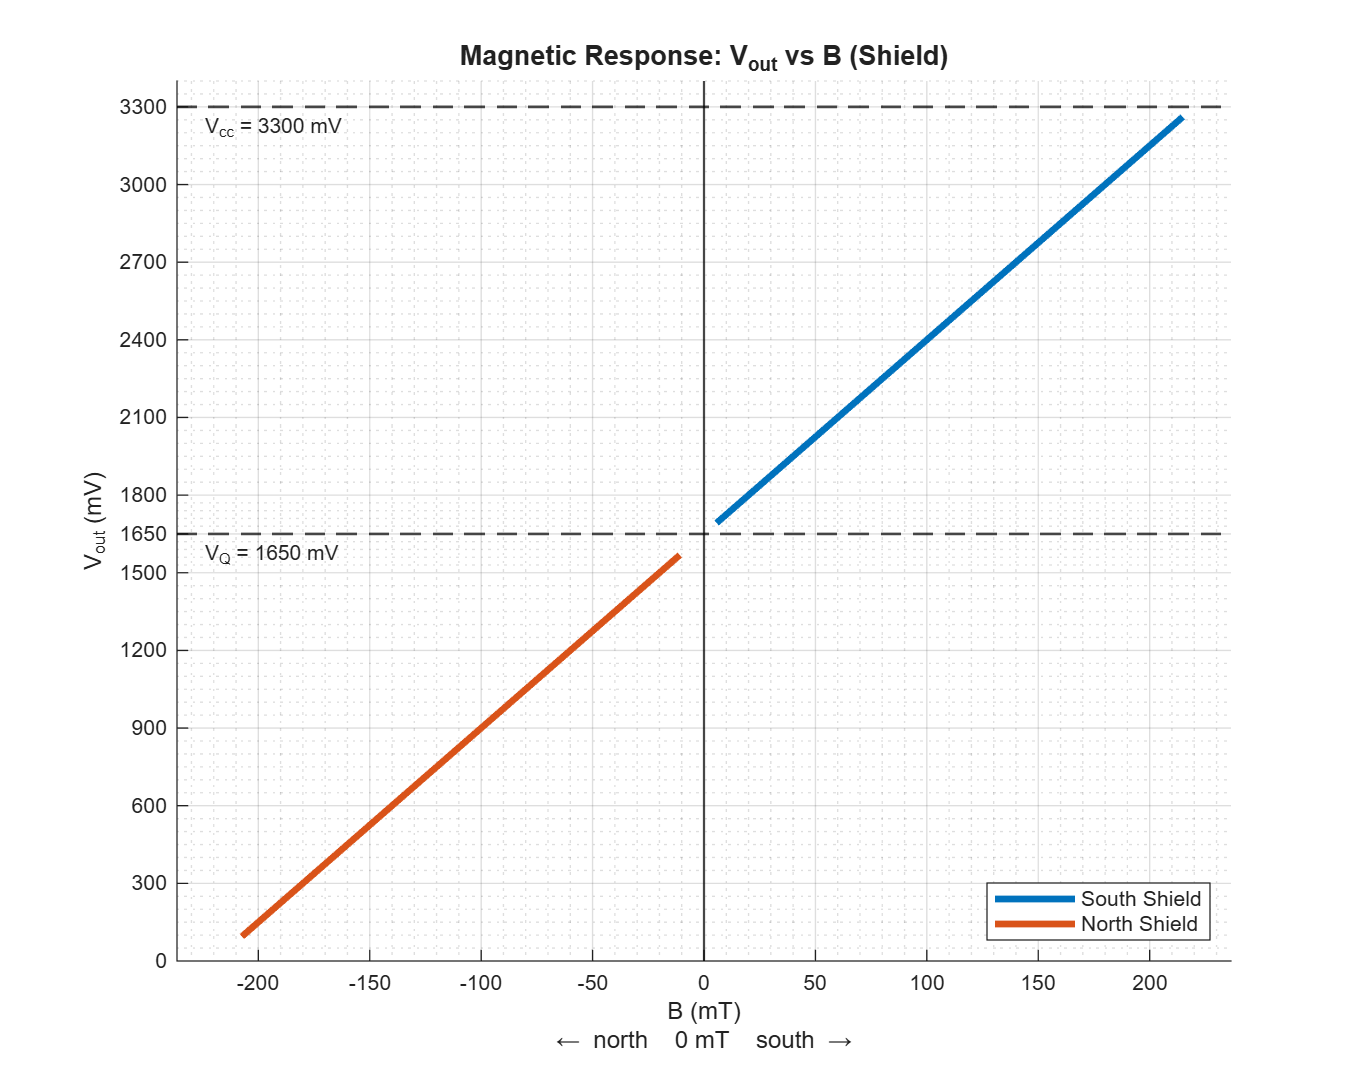


% ====================================================
% STEP 3: Vout vs B — Shield conditions only
% ====================================================
fig_vb = figure('Position',[100 100 680 540]);
hold on;

shield_conds  = [2, 4];
shield_colors = {'#0072BD', '#D95319'};
shield_labels = {'South Shield', 'North Shield'};

all_b_shield = [];
for idx = 1:2
    c = shield_conds(idx);
    for s = 1:3
        all_b_shield = [all_b_shield; all_data{c,s}.B_mT];
    end
end
xl = max(abs(all_b_shield)) * 1.1;

for idx = 1:2
    c = shield_conds(idx);
    B_avg    = mean([all_data{c,1}.B_mT,      all_data{c,2}.B_mT,      all_data{c,3}.B_mT],    2);
    Vout_avg = mean([all_data{c,1}.V_out_mV,   all_data{c,2}.V_out_mV,   all_data{c,3}.V_out_mV],2);
    [B_s, ii] = sort(B_avg);
    plot(B_s, Vout_avg(ii), '-', ...
        'Color', shield_colors{idx}, 'LineWidth', 2.5, ...
        'DisplayName', shield_labels{idx});
end

xline(0,    '-k',  'LineWidth', 0.8, 'HandleVisibility','off');
yline(V_Q,  '--k', 'LineWidth', 1,   'HandleVisibility','off');
yline(V_ref,'--k', 'LineWidth', 1,   'HandleVisibility','off');

text(-xl*0.95, V_ref - 80, 'V_{cc} = 3300 mV', 'FontSize', font_ax, 'HorizontalAlignment','left');
text(-xl*0.95, V_Q  - 80, 'V_Q = 1650 mV',    'FontSize', font_ax, 'HorizontalAlignment','left');

xlim([-xl, xl]);
ylim([0, 3400]);
yticks(unique([0, 300:300:1500, 1650, 1800:300:3300]));

ax = gca;
ax.XAxis.FontSize = font_ax;
ax.YAxis.FontSize = font_ax;

xlabel(sprintf('B (mT)\n←  north    0 mT    south  →'), 'FontSize', font_ax+1, 'HorizontalAlignment','center');
ylabel('V_{out} (mV)', 'FontSize', font_ax+1);
title('Magnetic Response: V_{out} vs B (Shield)', 'FontSize', 10);
legend('Location','southeast', 'FontSize', font_ax);
grid on; grid minor;

saveas(fig_vb, 'fig_Vout_vs_B_shield.png');


% ====================================================
% STEP 4: Shield Comparison Table
% ====================================================
fprintf('\n=== Shield Comparison Table ===\n');


=== Shield Comparison Table ===


for pole = 1:2
    if pole == 1; c_no=1; c_s=2; pname='South'; else; c_no=3; c_s=4; pname='North'; end

    d_vals   = all_data{c_no,1}.Distance_cm;
    B_no_avg = mean([all_data{c_no,1}.B_mT, all_data{c_no,2}.B_mT, all_data{c_no,3}.B_mT],2);
    B_s_avg  = mean([all_data{c_s,1}.B_mT,  all_data{c_s,2}.B_mT,  all_data{c_s,3}.B_mT], 2);
    delta_B  = B_no_avg - B_s_avg;

    fprintf('\n%s Pole\n', pname);
    fprintf('%-10s %-20s %-18s %-12s\n','d (cm)','B_no_shield (mT)','B_shield (mT)','ΔB (mT)');
    fprintf('%s\n', repmat('-',1,62));
    for i = 1:length(d_vals)
        fprintf('%-10.1f %-20.4f %-18.4f %-12.4f\n', ...
            d_vals(i), B_no_avg(i), B_s_avg(i), delta_B(i));
    end
    fprintf('%-10s %-20.4f %-18.4f %-12.4f\n','Mean', ...
        mean(B_no_avg), mean(B_s_avg), mean(delta_B));

    T_out = table(d_vals, B_no_avg, B_s_avg, delta_B, ...
        'VariableNames',{'Distance_cm','B_no_shield_mT','B_shield_mT','Delta_B_mT'});
    writetable(T_out, sprintf('shield_comparison_%s.csv', pname));
end


South Pole


d (cm)     B_no_shield (mT)     B_shield (mT)      ΔB (mT)     


--------------------------------------------------------------


0.0        212.7809             213.4222           -0.6413     
0.2        214.1952             214.7814           -0.5862     
0.4        214.2931             214.8184           -0.5253     
0.6        214.0816             214.2226           -0.1410     
0.8        194.4365             141.3112           53.1253     
1.0        128.9757             97.0285            31.9472     
1.2        87.6926              69.2865            18.4061     
1.4        61.2762              51.3282            9.9479      
1.6        42.9130              37.4663            5.4467      
1.8        31.6157              27.0783            4.5374      
2.0        24.0664              21.9335            2.1329      
2.2        19.2161              17.2534            1.9627      
2.4        15.3373              13.8514            1.4859      
2.6        11.8866              11.1091            0.7775      
2.8        9.2121               9.0972             0.1149      
3.0        7.6214               7.5649  

Mean       83.3547              76.3172            7.0375      



North Pole


d (cm)     B_no_shield (mT)     B_shield (mT)      ΔB (mT)     


--------------------------------------------------------------


0.0        -206.8452            -205.9733          -0.8719     
0.2        -208.4041            -207.3815          -1.0225     
0.4        -207.7097            -206.7546          -0.9551     
0.6        -206.9348            -205.8790          -1.0558     
0.8        -188.9596            -150.6957          -38.2639    
1.0        -123.4822            -99.2625           -24.2197    
1.2        -88.6905             -72.5744           -16.1161    
1.4        -62.0942             -54.5190           -7.5752     
1.6        -46.3683             -41.1681           -5.2002     
1.8        -35.0400             -32.2715           -2.7685     
2.0        -28.7257             -26.4514           -2.2744     
2.2        -23.7259             -22.2835           -1.4425     
2.4        -20.4218             -19.0619           -1.3599     
2.6        -17.3751             -16.1691           -1.2060     
2.8        -16.6953             -14.0869           -2.6083     
3.0        -15.3917             -12.6340

Mean       -84.4963             -78.3169           -6.1794     



fprintf('\nAll done.\n');


All done.
